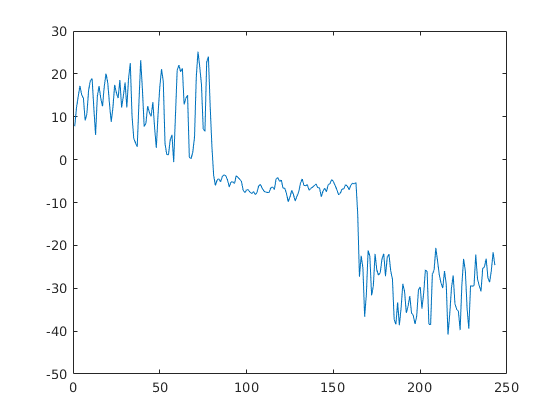

dataset = csvread('train_data.csv');
accX = medfilt1(dataset(:, 1));
accY = medfilt1(dataset(:, 2));
accZ = medfilt1(dataset(:, 3));
w_size = 20;
num_w = floor(2 * length(accX) / w_size) - 1;
d = 1;
x = zeros(num_w, w_size);
for i = 1:num_w
    x(i, :) = accX(d: (d + w_size - 1), 1);
    d = d + w_size/2;
end
d = 1;
y = zeros(num_w, w_size);
for i = 1:num_w
    y(i, :) = accY(d: (d + w_size - 1), 1);
    d = d + w_size/2;
end
d = 1;
z = zeros(num_w, w_size);
for i = 1:num_w
    z(i, :) = accZ(d: (d + w_size - 1), 1);
    d = d + w_size/2;
end

labels = csvread('train_labels.csv');
d = 1;
l = zeros(num_w, w_size);
for i = 1:num_w
    l(i, :) = labels(d: (d + w_size - 1), 1);
    d = d + w_size/2;
end
csvwrite('Acc_x.csv', x);
csvwrite('Acc_y.csv', y);
csvwrite('Acc_z.csv', z);
csvwrite('Label.csv', mode(l, 2));
features = std(x,0, 2) - std(z, 0, 2);
csvwrite('feature_vector.csv', features);
plot(features);